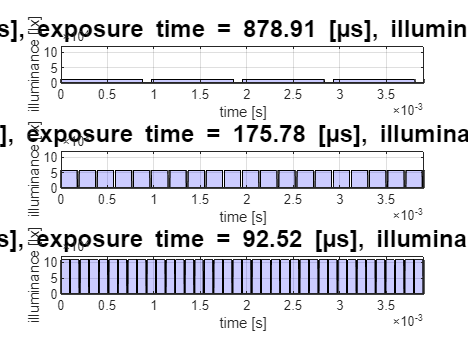

clear, clc;
% This program simulates the exposure time for dynamic control of LSC and
% line light

% Variables
conv_speed = [0.2, 1, 1.9];                 % [m/s]
num_of_periods = 4;

% Knowns
F_stop = 2;                     % F-stop of camera
C = 250;                        % incident light meter calibration standard
ISO = 100;
pixel_size = 0.4/4096;          % physical representation of pixel [m]
pixels_trigger = 2;             % Every trigger acquires two rows of pixels



% trigger calculations
trig_freq = conv_speed./(pixel_size*pixels_trigger);
trig_period = 1./trig_freq;

% illuminance calculations
t_exp = 0.9.*trig_period;
EV = log2(F_stop.^2./t_exp);
illuminance = (2.^EV*C)./ISO;

% plots

for i = 1:length(conv_speed)
    subplot(length(conv_speed), 1, i)

    t = linspace(0, trig_period(1)*num_of_periods, 2000);
    LSC_exp = PWM(trig_freq(i), 0, illuminance(i), t_exp(i)*100/trig_period(i), t);
    
    fill_handle_LSC = fill([t fliplr(t)], [LSC_exp zeros(size(LSC_exp))], 'b', 'FaceAlpha', 0.2);
    
    ylim([0 120000])
    xlim([0 trig_period(1)*num_of_periods])
    title("\fontsize{16}Speed = " + conv_speed(i) + " [m/s], exposure time = " + round(t_exp(i)*1000000, 2) + " [µs], illuminance = " + round(illuminance(i)/1000,2) + " [klx]")
    ylabel("illuminance [lx]")
    xlabel("time [s]")
    grid on

end